# Analysis of Differentially Expressed Genes in Alzheimer's Disease in H. Sapiens and M. Musculus.

### Authors: Kristen Norray, Zeal Jinwala, Henry Hollis

## Analysis of M. Musculus dataset 1:

%download and parse GSE from mouse experiement
mus_gse_1 = bmes_downloadandparsegse_modified('GSE112847');

Reading /private/var/folders/y2/wb9g1qtn2wd62g4bfpcdp00m0000gn/T/GSE112847.txt ...


platform = mus_gse_1.Header.Series.platform_id;
mus_gpl_1 = bmes_downloadandparsegpl_modified(platform);

mus_g_1 = mus_gse_1.Data;
mus_g_1 = z_norm_expr_data(mus_g_1); %z_norm the data
% qn_mus_g_1 = quantilenorm(mus_g_1.double());
% qn_mus_g_1 = bioma.data.DataMatrix(qn_mus_g_1);
% qn_mus_g_1 = qn_mus_g_1.rownames(':',mus_g_1.rownames);
% qn_mus_g_1 = qn_mus_g_1.colnames(':',mus_g_1.colnames);
% mus_g_1 = qn_mus_g_1;
[gsegenes, ind_of_mapped] = translate_probes(mus_gpl_1, mus_g_1, 'GB_ACC', 'ID');
mus_g_1 = mus_g_1.rownames(':',gsegenes);              %renames the rows
mus_g_1 = mus_g_1(find(ind_of_mapped),:);           %only keeping genes that mapped to the gpl

Do the conditions cluster together?

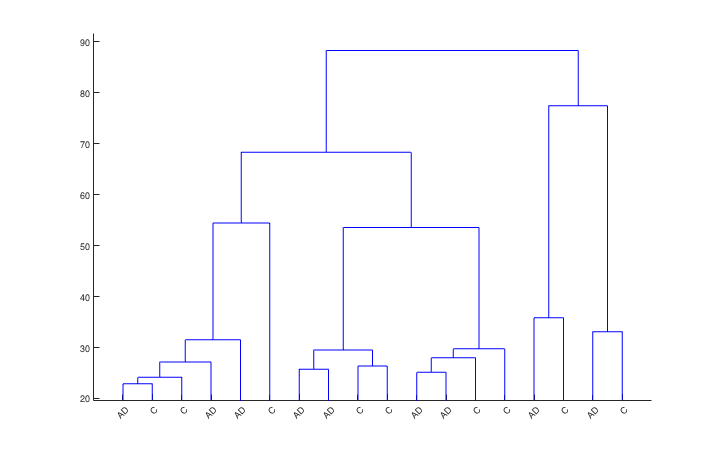

samplegroups = mus_gse_1.Header.Samples.characteristics_ch1(2,:);
colnames= mus_g_1.colnames;
clusterSamples(mus_g_1, colnames, samplegroups, 'genotype: APP+/+', 'genotype: APP-/-','AD', 'C')

sigfc = get_de_genes(mus_g_1, samplegroups, 'genotype: APP+/+', 'genotype: APP-/-', 1000);

Found 2 genes with pvalue<=0.05 and FC>=0.58.


disp(sigfc(:, 1:2))

                    p-values      log2fc  
    NM_001198823    7.1776e-06      2.1038
    NM_013697         0.046336    -0.69297



## Analysis of M. Musculus dataset 2:

%download and parse GSE from mouse experiement
mus_gse_2 = bmes_downloadandparsegse_cached('GSE106643');

platform = mus_gse_2.Header.Series.platform_id;
mus_gpl_2 = bmes_downloadandparsegpl_modified(platform);

mus_g_2 = mus_gse_2.Data;
%mus_g_2 = z_norm_expr_data(mus_g_2); %z_norm the data

[gsegenes, ind_of_mapped] = translate_probes(mus_gpl_2, mus_g_2, 'mrna_assignment', 'ID');  
gsegenes = strip(regexprep(gsegenes, "(?<= ).*", ""));
mus_g_2 = mus_g_2.rownames(':',gsegenes);              %renames the rows
mus_g_2 = mus_g_2(find(ind_of_mapped),:);            %only keeping genes that mapped to the gpl

samplegroups = mus_gse_2.Header.Samples.characteristics_ch1(1,:);
colnames= mus_g_2.colnames;
clusterSamples(mus_g_2, colnames, samplegroups, 'genotype/variation: Tg2576 transgenic', 'genotype/variation: WT','AD', 'C')

sigfc = get_de_genes(mus_g_2, samplegroups, 'genotype/variation: Tg2576 transgenic', 'genotype/variation: WT', 1000);
sigfc(1:10, 1:2)

## Analysis of H. Sapien transcriptome data:

gse = bmes_downloadandparsegse('GSE63063', 'GPL6947');

Reading /private/var/folders/g8/824tqwk50c17j0sh1y69p4z5x108l_/T/GSE63063.txt ...


g = gse.Data;
platform = gse.Header.Series.platform_id;
platforms = strsplit(platform, "\n");
gpl = bmes_downloadandparsegpl(platforms{1});

Map Probes to Gene Symbols:

[gsegenes, MAP_GSE_GPL] = translate_probes(gpl, g, 'ORF');  
g = g.rownames(':',gsegenes);              %renames the rows

Error using bioma.data.DataMatrix/subsref (line 145)
Number of row names (1) does not match the number of rows (38323).

keep_rows = ~strcmp(g.rownames, '');       %removing blank gene names
g = g(keep_rows, :);

# EVERYTHING BELOW THIS IS JUST FROM "MA" AND IS JUST FOR REFERENCE TO BE DELETED LATER

samplegroups = gse.Header.Samples.characteristics_ch2(1,:);

samplesources = gse.Header.Samples.source_name_ch2;
disp(samplesources(1:10))  %print out the brain region where samples were taken
colnames= g.colnames;
for i=1:numel(colnames)
    if strcmp(samplesources{i},'yeast treated with 1% DMSO for 5 hours')     %assign samp to control group
        colnames{i} = 'DMSO';
  
    elseif strcmp(samplesources{i},'yeast treated with 80 µM CQ for 5 hours') %assign sample to CQ group
            colnames{i} = 'CQ';
    
    else
        colnames{i} = 'NA';
        
    end
end

assert(~any(strcmp(colnames, 'NA')))  %make sure all columns are assigned
g =g.colnames(':',colnames);          %rename the columns of our data

## Hierarchical Sample Clustering

treeNames = colnames;
for i=1:numel(colnames)
    treeNames{i} = [colnames{i} ' - Col' num2str(i)];
end
tree = linkage(g.double()','average');
dendrogram(tree,'Labels',treeNames);
h=gca;
h.XTickLabelRotation=45;

## Clustergram

% keep genes that vary most across samples
% (ingoring sample groups.)
I=genevarfilter(g, 'Percentile',95); %remove 95% of genes

g2 = g(I,:);
clustergram(g2,'Standardize','Row')

## Differential Expression: Top 10 Most Different Genes Between Groups

CQ_cols = strcmp(colnames, 'CQ');
DMSO_cols = strcmp(colnames, 'DMSO');
[gpvals]=mattest(g(:,DMSO_cols), g(:,CQ_cols), 'permute',100);  %non parametric mattest

%data is not log transformed so we do that now
log2fc = log2( mean(g(:,CQ_cols),2) ./ mean(g(:, DMSO_cols),2) );

%making the volcano plot
scatter(log2fc, -log10(gpvals(:,1)), '.');
xlabel('log_2(CQ:Control)'), ylabel('-log_{10}(pvalue)');
%mark fc>=1.5 and pvalue<=0.01
hold on;
plot(log2([2/3 2/3]), ylim, log2([1.5 1.5]), ylim)
plot(xlim, -log10([.01 .01]))
ylim([0, 6]);

% Add the foldchange information to the gpvals object:
gpvals=[gpvals bioma.data.DataMatrix(log2fc,'ColNames',{'log2fc'})];
gpvals =[gpvals bioma.data.DataMatrix(abs(log2fc),'ColNames',{'abs_log2fc'})];
% Select the genes with pvalue<=0.01 and FC>=1.5.
keep = gpvals(:,'p-values')<=0.01 & abs(gpvals(:,'log2fc'))>=1.5;
write_to_excel(gpvals, 0.01);      %write out the significantly modulated genes for GSEA
sigfc = gpvals(keep,:);
sigfc = sigfc.sortrows('abs_log2fc', 'descend');
fprintf('Found %d genes with pvalue<=0.01 and FC>=1.5. Showing top 10 \n',size(sigfc,1));

### One method for finding highest fold change and significant genes is filtering out non significant genes and then sorting by abs(fold change):

disp(sigfc(1:10,1:2))

### Another metric would be weighted euclidean distance (once we removed all the non-sig genes):

sigfc_euc =[sigfc bioma.data.DataMatrix(sqrt(10*sigfc(:,2).^2 + (-log10(sigfc(:,1))).^2),'ColNames',{'euc_distance'})];
%giving some extra weight to fc because we're not extremely interested in
%extreme difference between 1e-5 and 1e-13 pvalues, for example.

sigfc_euc = sigfc_euc.sortrows('euc_distance', 'descend');
disp(sigfc_euc(1:10,1:2))

## Functional Annotations 

KEGG Library for DAVID over-representation pathway analysis:

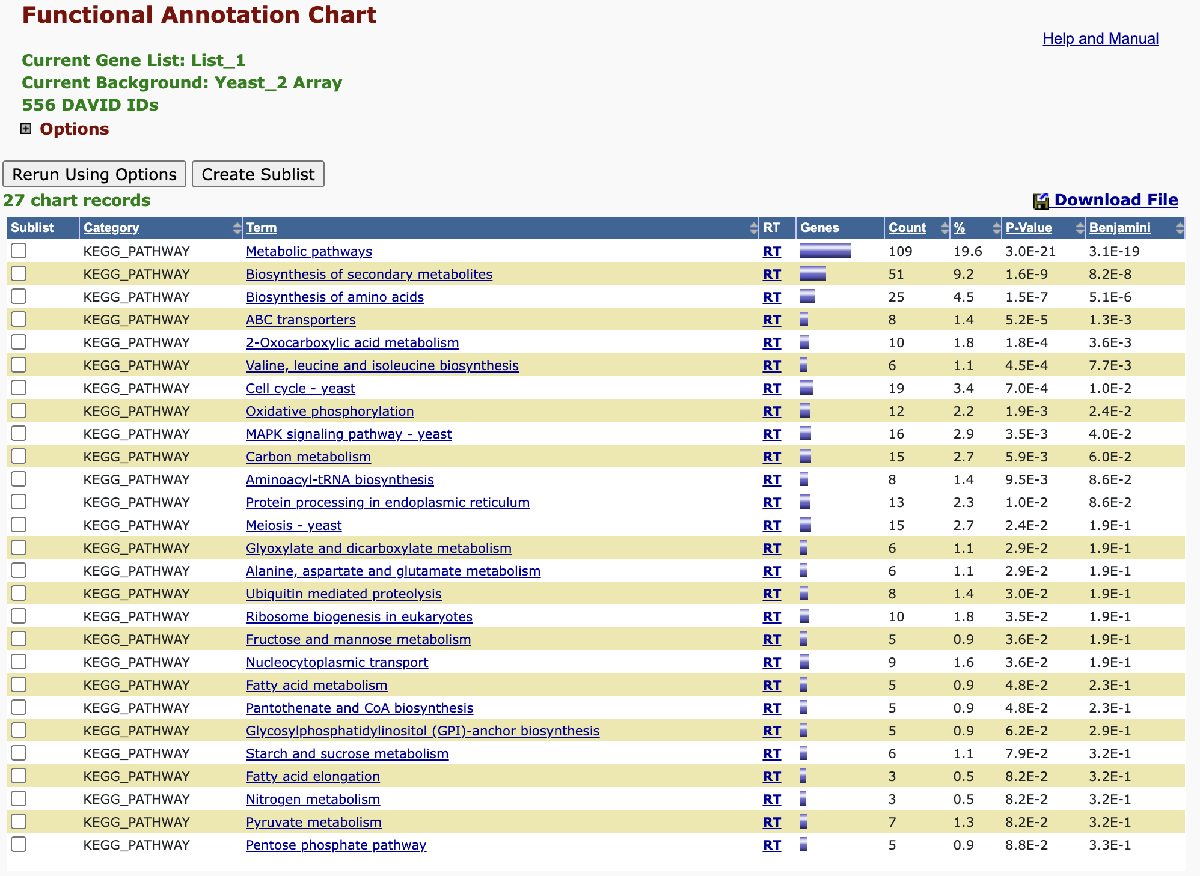

GO:BP Library:

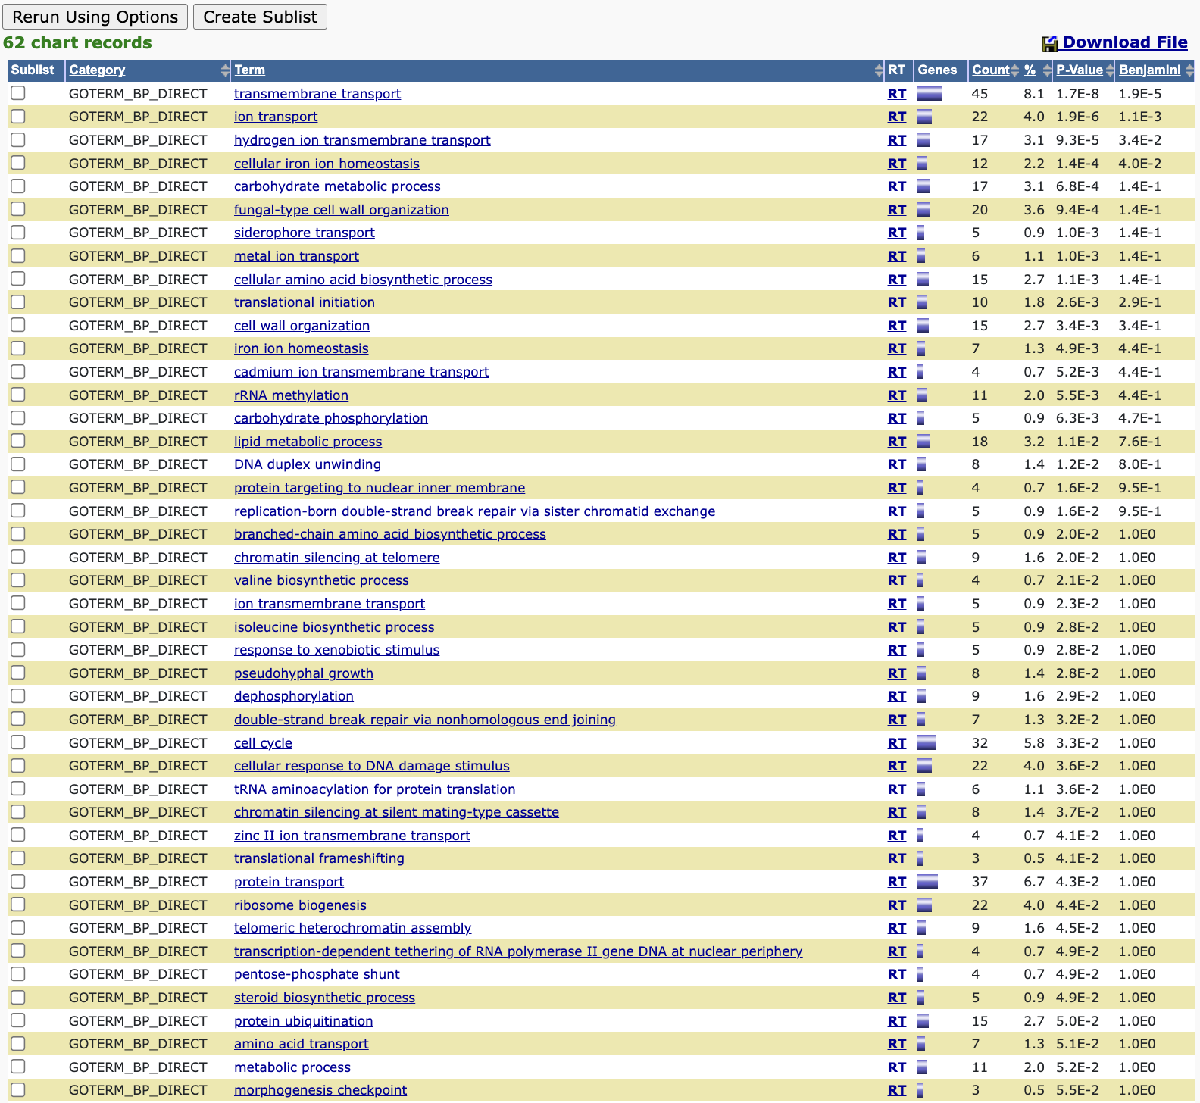

## How does this compare to the paper?

The authors found that many metal ion transport genes were upregulated in response to CQ treatment. Indeed, searching my unfiltered gene list returns these genes (from Tab 1) and their high fold changes. However, because I use non-parametric methods (as opposed to the unpaired t-test the authors use) to determine significance, I lose some of these genes when I filter for p<0.01. Nevertheless, 'metal-ion transport,' 'iron ion homeostasis,' 'Zinc II transmembrane transportation' are all significantly enriched pathways, in agreement with the authors' findings. 

Moreover, the authors find evidence for a decrease in activity of some metal-dependant enzymes in yeast with CQ treatment. Specifically, the copper dependent enzyme CcO is reduced. My KEGG pathway analysis suggests the "metabolic pathways" pathway is significantly enriched in my differentially expressed gene list. Indeed, once I clicked to find which genes led DAVID to this conclusion, the CcO subunits were all present:

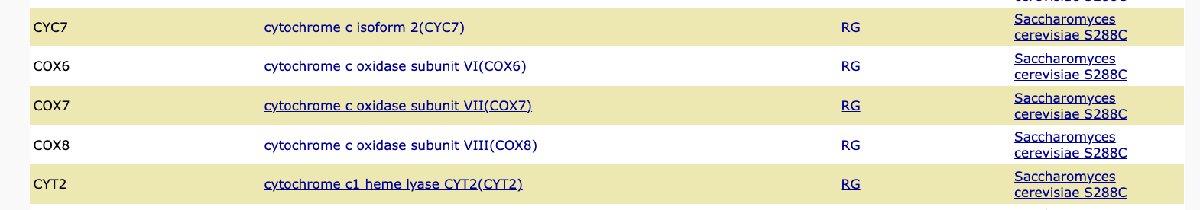

In light of this, these results agree generally well with what Chenghua et al. found.